%{
ES115 Engineering Computer Applications 
Module 1 Project: Water Tank Fill-and-Drain

Author: Luis A. Lamas Carreto
Instructor: Lynroy Grant
Date: April 23, 2026

Purpose:
The purpose of this project is to model the changing volume of a water tank using a
 piecewise function to represent two distinct stages: filling and draining. 
By using MATLAB to calculate and plot these phases, we can track how fast the water
 level rises and falls, identify exactly when the tank hits specific volume targets,
 and organize the data into clear tables for monitoring. This approach demonstrates
 how engineers use math to simulate and manage liquid storage systems.

Inputs:
- Time Range (t): 0 to 25 minutes
- Step Size: 1 minute
- Filling Equation: (V(t) = 5t + 20) (for (0 < t < 10)
- Draining Equation: (V(t) = -3(t - 10) + 70) (for(10 < t < 25)

Outputs:
- Volume Vector (V): Liters of water calculated at every minute
- Time Check: Identification of time points where volume equals 50 liters
- Data Table: A 12+ row summary of time vs. volume
- Visualization: A line plot showing the transition from filling to draining

Engineering Workflows:
- Piecewise Modeling: Using different mathematical rules for different time intervals
- Flow Rate Analysis: Interpreting slopes as net filling and draining rates
- Intersection Analysis: Locating specific system states (50L mark) within a time series.

MATLAB Tools:
- Logical Indexing: Applying equations to specific segments of a vector (e.g., t <= 10)
- zeros(): Pre-allocating the volume vector for efficiency
- table(): Organizing discrete data points into a structured format
- plot(): Graphing the volume profile to visualize the peak and slopes
%}


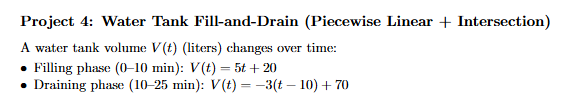

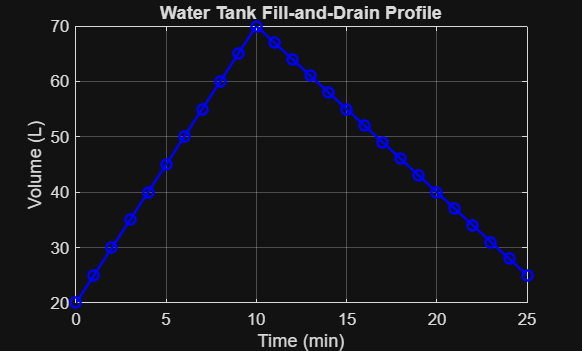

t = 0:1:25;

V = zeros(size(t));
V(t <= 10) = 5*t(t <= 10) + 20;               
V(t > 10) = -3*(t(t > 10) - 10) + 70;         

figure;
plot(t, V, 'b-o', 'LineWidth', 1.5);
grid on;
xlabel('Time (min)');
ylabel('Volume (L)');
title('Water Tank Fill-and-Drain Profile');


t_at_50 = t(V == 50);
fprintf('Tank reaches 50L at: %s minutes\n', num2str(t_at_50));

Tank reaches 50L at: 6 minutes



t_table = t(1:2:end)'; 
V_table = V(1:2:end)';
TableResults = table(t_table, V_table, 'VariableNames', {'Time_min', 'Volume_L'});
disp(TableResults);

    Time_min    Volume_L
    ________    ________

        0          20   
        2          30   
        4          40   
        6          50   
        8          60   
       10          70   
       12          64   
       14          58   
       16          52   
       18          46   
       20          40   
       22          34   
       24          28   




fprintf('\nInterpretation:\n');


Interpretation:


fprintf('Filling Phase Slope (+5): Represents the filling rate of 5 L/min.\n');

Filling Phase Slope (+5): Represents the filling rate of 5 L/min.


fprintf('Draining Phase Slope (-3): Represents the draining rate of 3 L/min.\n');

Draining Phase Slope (-3): Represents the draining rate of 3 L/min.
